# Merging of clusters in the graph data

## Intention

In this script we want to sparsify the graph data we receive from Tristan.

In the data of the nodes we got at each spatial point a cluster of multiple nodes (around 27). The angles of the overlapping node clusters are unanimous whereas the bearings of each node differ.

## Preparations

addpath("functions")
addpath("CircStat2012a")
format shortG

[nodes,edges] = readBoth("data\small_graph");

Interestingely enough we got nodes with labels 0 to 1371, whereas the node with label 0 does not matter in a way other than initialize the graph as it gets build by Tristan's algorithm. 

So in the small graph data we do not have n = 1372 nodes but n = 1371. This is reflected in the edges data in the way that their labels only go from 1 to 1371.

To compensate with this, we exclude the first line of nodes in **readBoth() **and reshuffle the edges there too.

all_nodes = nodes;
all_edges = edges;

The variable **n **describes the number of nodes in the graph. Here we go for one node for each line in our nodes graph data. 

In future works we might want to cluster nodes or merge the ones that initialy lie on the same spatial coordinates. This future work is presicely what follows below. As to this, we initiate **n **only after our process of merging.

## Merging nodes

The following **unique()** call gives the rows with the first occurences of a position vector. 

Additionally, the indices for the row (in our case same as the **label **column) and clusterings (each overlaying points are the same cluster) are returned.

[~,IA,~] = unique(nodes(:,[2 3]),'rows','stable');

These arrays will be used to merge the edges of a cluster in a specific fashion. The remaining nodes will be called **representatives**.

nodes = nodes(IA,:);  % these nodes are the representatives

Let's now assign **n **as the number of representatives.

n = size(nodes,1)

n =     50


The following plot does show the same graph as the non-merged version, but intrinsically there are no overlapping nodes on the same spatial point. 

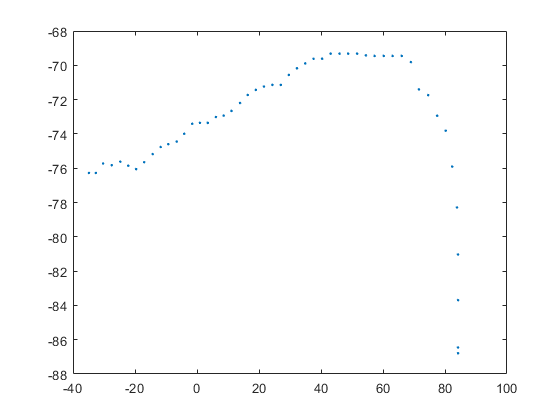

plot(nodes(:,2),nodes(:,3),".")

## Merging edges

As we did merge multiple nodes to one just now we need to update the edges, namely their respective **from **and **to **nodes will be exchanged for the respective **representative**.

After trying brute force approaches, a worst case running time of order **O(n*e) with n=#nodes, e=#edges **is to be expected.

To optimize the order of magnitude we try another approach of the form ...

% TODO

We build matrices for the **from** and the **to **columns with the representatives (their nodes labels are the array of **IA**). Here we check the smaller-greater relations of each edge node with each representative.

maf = edges(:,2)' < IA;
mat = edges(:,3)' < IA;

With these matrices we test for the last representative that is smaller than the current **from** and **to** nodes respectively and update them edges.

for i = 1:size(edges,1)
    [~,ia,~] = unique(maf(:,i),'last');
    ia(1);
    edges(i,2) = IA(ia(1));
    
    [~,ia,~] = unique(mat(:,i),'last');
    edges(i,3) = IA(ia(1));
end

Due to the nature of Tristans search algorithm the updated edges do sometimes result in self loops. We do exclude these edges.

selfloops = edges(:,2)==edges(:,3);
edges(selfloops,:) = [];

## Relabeling

To be able to work with **edges** and **nodes** we need to renumber the labels of the nodes from 1 to **n**.

mapping = [(1:length(IA))' IA]

mapping =      1     1
     2    30
     3    49
     4    73
     5   103
     6   133
     7   163
     8   193
     9   223
    10   253


nodes(:,1) = 1:size(nodes,1);
edges(:,1) = 1:size(edges,1);
for i = 1:size(edges,1)
    idx = find(edges(i,2)==mapping(:,2));
    edges(i,2) = idx;
    
    idx = find(edges(i,3)==mapping(:,2));
    edges(i,3) = idx;
end

## Circular mean

*(using code from toolbox *[https://de.mathworks.com/matlabcentral/fileexchange/10676-circular-statistics-toolbox-directional-statistics)](https://de.mathworks.com/matlabcentral/fileexchange/10676-circular-statistics-toolbox-directional-statistics))

The north direction is consistent over each cluster of merged nodes, thus it does not need to be changed in any way.

The bearing/vote on the other hand does vary over the merged cluster. To compensate the loss of information as good as possible be calculate for the representative the circular mean over all bearings in the respective nodes cluster.

% all representatives get circ_mean bearing
% first all but last, then last too
for i = 1:n-1
    nodes(i,4) = circ_mean(all_nodes(IA(i):IA(i+1)-1,4));
end
nodes(end,4) = circ_mean(all_nodes(IA(n):end,4));

## Aftermath

clc
clearvars -except nodes edges n
save materials\merged.mat